Choose parameters

m = 16;
N = 200000;

Create data

% obj = ResultManager;
% obj = obj.generate_res(m, N);
% %%%% histogram
% d = obj.res_minsingvals;
N2 = 50000

N2 = 50000

obj = obj.add_new_res(N2);


Some descriptive statistics

%%%% plot histogram
min_d = min(d)

min_d = 1.9304e-08

max_d = max(d)

max_d = 0.0760

%%% create edges
% parameter (for tails)
min_d_rel = min_d * 2^m

min_d_rel = 0.0013

**Min singvals**

clf
thresh = 2^(-(m-8))

thresh = 0.0039

nbins_coarse = 10

nbins_coarse = 10

edges_coarse = linspace(0, thresh, nbins_coarse)

edges_coarse =          0    0.0004    0.0009    0.0013    0.0017    0.0022    0.0026    0.0030    0.0035    0.0039


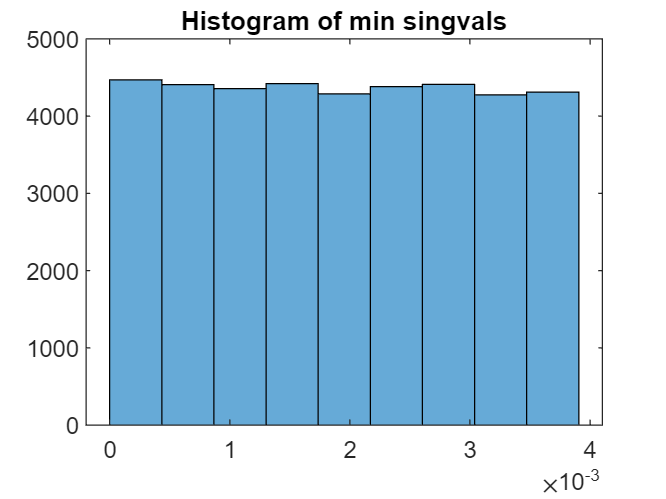

% my_median = median(d)
%%% histogram
histogram(d, edges_coarse)
title("Histogram of min singvals")

%%% cumulative histogram
nbins_finer = 30

nbins_finer = 30

edges = linspace(0, thresh, nbins_finer)

edges =          0    0.0001    0.0003    0.0004    0.0005    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0015    0.0016    0.0018    0.0019    0.0020    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0030    0.0031    0.0032    0.0034    0.0035    0.0036    0.0038    0.0039


% plot cumulative histogram
h = histogram(d, edges,'Normalization','cdf');
title("Cumulative (normalized) histogram of min singvals")
% plot linear approximation of tail [0, small number]
x0 = max(edges)

x0 = 0.0039

y0 = max(h.Values)

y0 = 0.1965

x = linspace(0, x0)

x =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0017    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0019


y = x * (y0/x0)

y =          0    0.0020    0.0040    0.0060    0.0079    0.0099    0.0119    0.0139    0.0159    0.0179    0.0199    0.0218    0.0238    0.0258    0.0278    0.0298    0.0318    0.0338    0.0357    0.0377    0.0397    0.0417    0.0437    0.0457    0.0476    0.0496    0.0516    0.0536    0.0556    0.0576    0.0596    0.0615    0.0635    0.0655    0.0675    0.0695    0.0715    0.0735    0.0754    0.0774    0.0794    0.0814    0.0834    0.0854    0.0874    0.0893    0.0913    0.0933    0.0953    0.0973


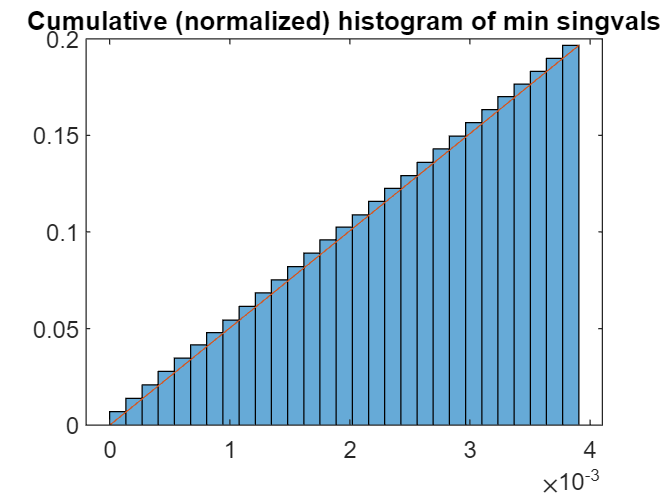

hold on
plot(x,y)
hold off

% Hypotheses:
% (3a) Distribution is 
	% uniform in the tail [m_min, 2^(-m) * 2^8] for some value of m_min.
	% none or almost none in [0,m_min] (not sure what hypothesis should be on this interval]
	% we don't investigate the distribution on [2^(-(m-4)), \infty)
% (3b) m_min = BigTheta(2^(-m)), and more precisely
%     m_min = 0.001 * 2^(-m).

Plot exponential tails

data = d;
eps_init = 2^(-m);
eps = 2^(-1);
n = 10;
[all_epses, all_tails_proportions] = tails(data, eps_init, eps, n)

all_epses = 1.0e-04 *

    0.1526    0.0763    0.0381    0.0191    0.0095    0.0048    0.0024    0.0012    0.0006    0.0003


all_tails_proportions = 1.0e-03 *

    0.7800    0.4000    0.2150    0.0950    0.0550    0.0250    0.0100    0.0050    0.0050    0.0050


%
k = size(all_epses, 2)

k = 10

x = linspace(1,k,k) % [k, k-1, ..., 1]

x =      1     2     3     4     5     6     7     8     9    10


y = all_tails_proportions

y = 1.0e-03 *

    0.7800    0.4000    0.2150    0.0950    0.0550    0.0250    0.0100    0.0050    0.0050    0.0050


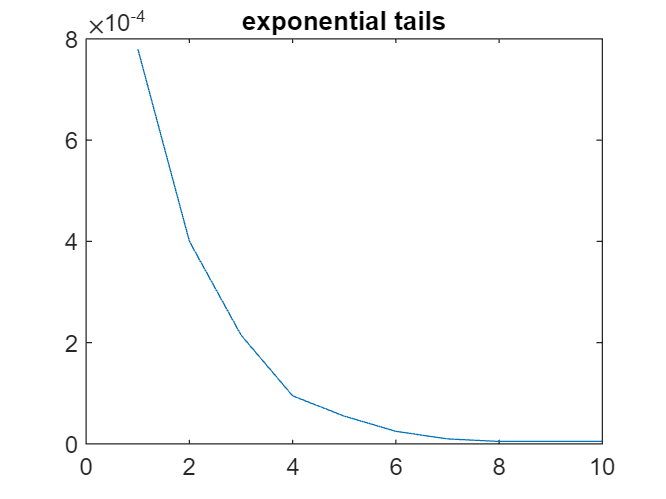

plot(x,y)
title("exponential tails")